# Vertical Stabilization system

In this exercise, we want to design a simple VS system for the JT-60SA tokamak. 

## Preliminaries

Elongated plasmas are unstable, due to the configuration of the magnetic field used to produce the elongated shape. This is shown qualitatively in the picture below:

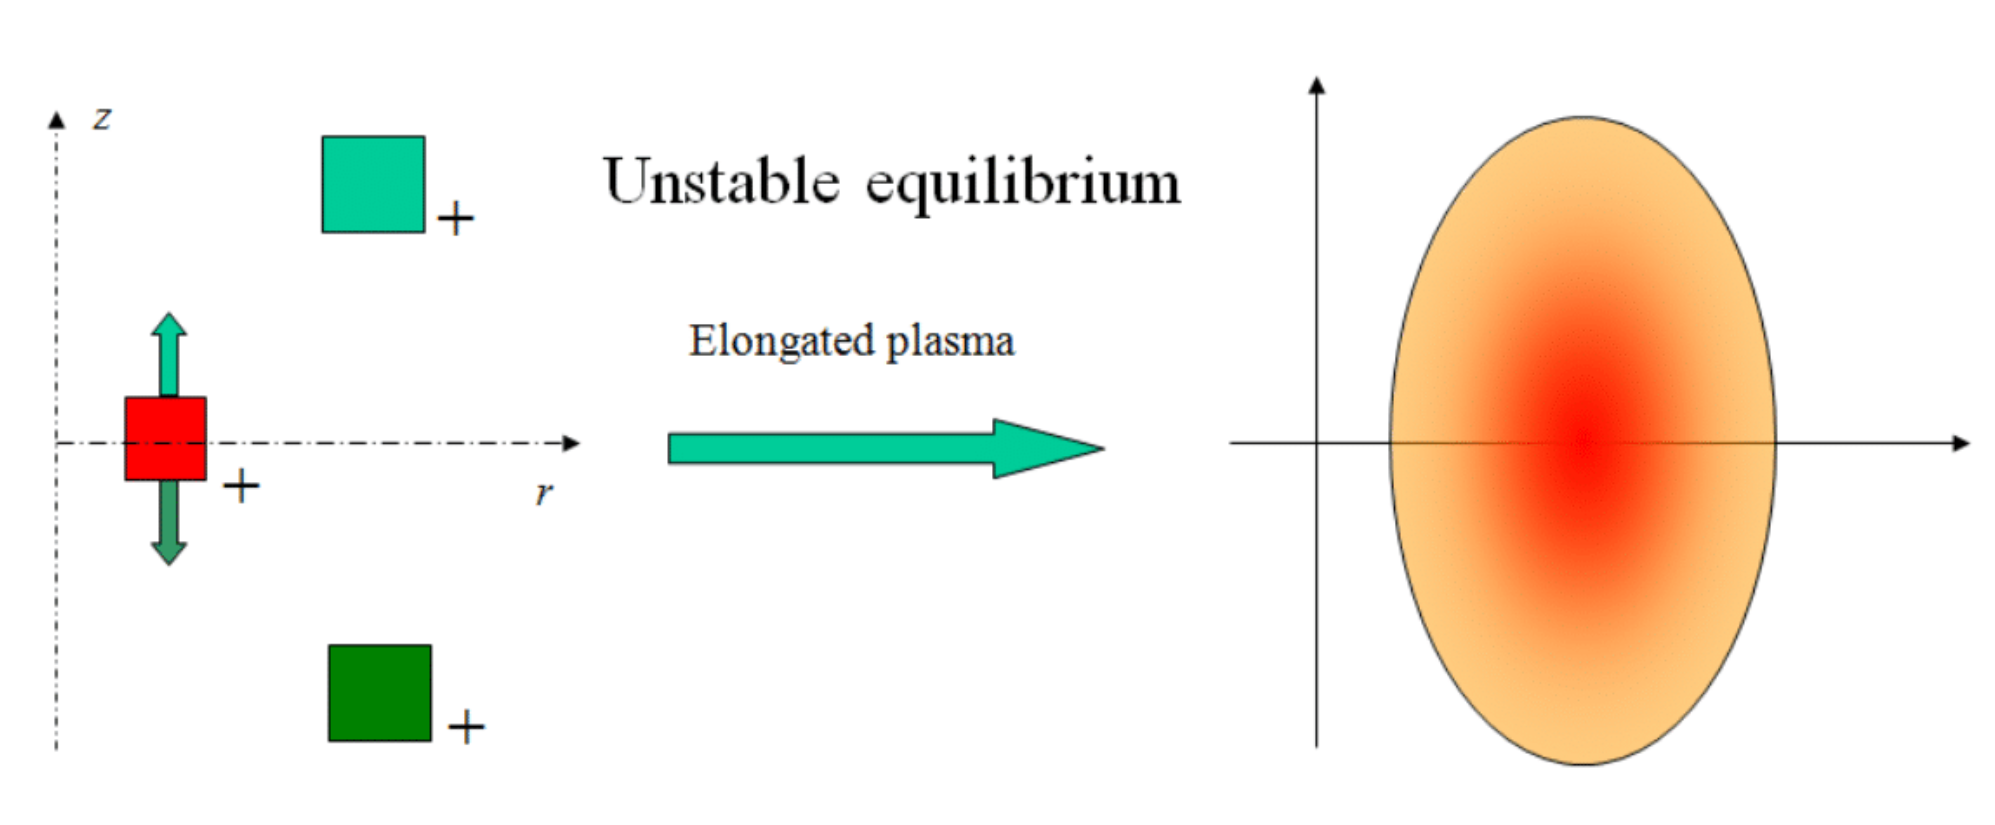

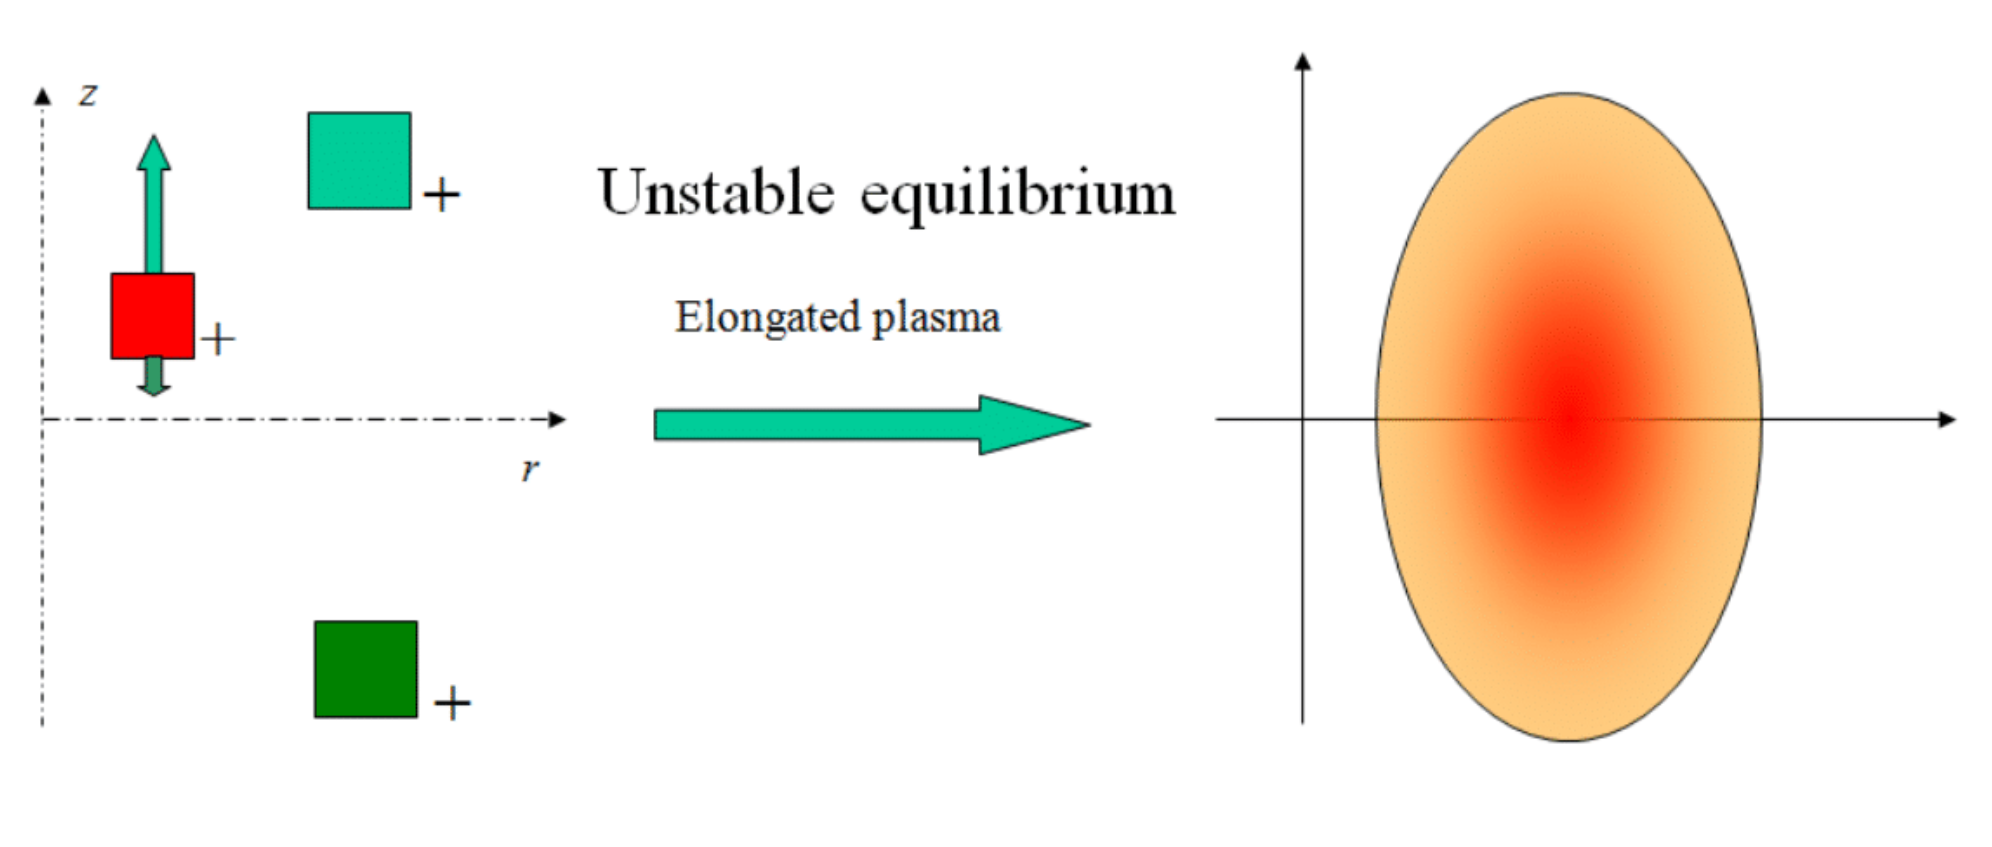

This instability can be detected already by using a very crude model of the plasma in a tokamak, i.e. a rigid filamentary current. For simplicity, we start by assuming the plasma current and radial position fixed:


$$L_a \dot{I}_a + R_a I_a + M_{ae} \dot{I}_e + \dot{\psi}_{ap}(z_p) = V_a \\
L_e \dot{I}_e + R_e I_e + M_{ea} \dot{I}_a + \dot{\psi}_{ep}(z_p) = 0 \\
m_p \ddot{z}_p = - 2 \pi r_p I_p B_r(z_p,I_a,I_e) $$


Let's start by considering the last equation. Elongated plasma configurations are generated through a *quadrupole* poloidal magnetic field. As a result, the radial component of the magnetic field varies along the vertical direction, as it can be seen in the figure below. In the same figure, you a vertical field component is also shown, which is needed to counteract the natural tendency of the plasma ring to expand. The expression for this vertical field can be computed explicitly (at least in simple cases) by analysing the *radial force balance* in a tokamak. However, for now it is sufficient to assume that some (static) vertical field is applied in order to keep the plasma in place (we'll take a closer look at why this is the case later on...)

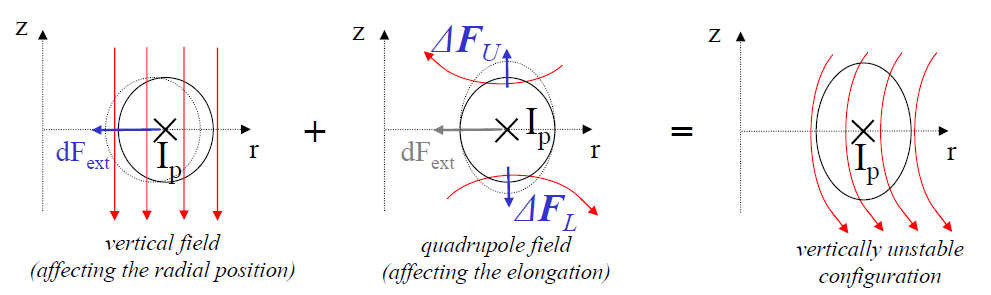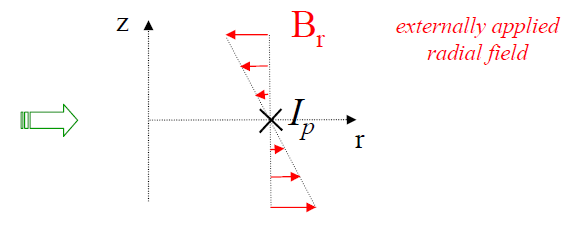

### Linearization of the filamentary model

To use this crude model for control design purposes, we should *linearize* it around the considered equilibrium position. 

Notice that equations (1) and (2) are linear, so the linearization procedure basically amounts to finding an expression for $B_r(z_p,I_a,I_e)$ in eq. (3) and taking its partial derivatives with respect to the state variables of our model (the currents $I_a, I_e$ and the vertical plasma position $z_p$)


$$m_p \ddot{z}_p \approx - 2 \pi r_p I_p \left[ \frac{\partial B_r}{\partial I_e} \delta I_a + \frac{\partial B_r}{\partial I_e} \delta I_e + \frac{\partial B_r}{\partial z_p} \delta z_p  \right]$$


The field can be expressed in terms of the gradient of the poloidal flux as 


$$B_r^{a,e} = -\frac{1}{2 \pi r_p} \frac{\partial \psi_{p,ae}}{\partial z}$$


where the flux enclosed by the plasma filament and generated by the external currents is $\psi_{p,ae} = M_{p,ae}I_{ae}$, and $M_{p,ae}$ are geometric mutual inductances (depending on $z_p$). Notice that, for this model, $B_r$ is actually linear in the currents, so we have 


$$\frac{\partial B_r}{\partial I_{a,e}} = -\frac{1}{2 \pi r_p} \frac{\partial M_{p,ae}}{\partial z_p} I_{a,e}$$


Computing the derivative with respect to $z_p$ is slightly more involved. Often, a quantity related to $\frac{\partial B_r}{\partial z}$ is defined, known as the **field index**


$$n:= -\frac{r_p}{B_V} \frac{\partial B_r}{\partial z}$$


Notice that this index is proportional to the derivative of the radial field $B_r$ in the vertical direction and that $B_r$ increases along the negative $z$ direction; $B_V$ is the vertical field generated by the active coils at the equilibrium and needed to achieve radial force balance (we'll give an expression for this quantity later, for now just assume that it is **constant** and points **downwards**). **We have a vertical instability whenever **$n>0$. Indeed, a displacement $\delta z_p$ from the equilibrium position results in a net vertical force given by


$$\delta F_z \approx -2\pi r_p I_p \delta B_r\approx 2 \pi I_p B_V n \delta z_p$$
 

An upward displacement results in an upward force, which pushes the plasma even *more* upward, resulting into instability. Before moving on, take a moment to appreciate the fact that even the **simplest possible model** of a plasma in a tokamak is capable of capturing this phenomenon (even if not in a very accurate way).

Also note that, due to the extremely small plasma mass $m_p$ and the large value of the plasma current $I_p$, the 'natural' time constant of this MHD instability is *awfully small, *usually in the order of $10^{-6}$s or even less! 

Luckily, the presence of **passive structures** surrounding the plasma (eq. (2) above) has a beneficial effect on this instability, bringing down its characteristic time scale to a more manageable value of $10^{-3} \div 10^{-1}$s (sometimes called the **resistive wall **time scale). 

Due to the separation of the time scales related to the inertial term and the Lorentz force, we often apply a *singular perturbation* argument, letting $m_p \rightarrow 0$ and substituting the resulting static relation between $\delta z_p$ and $\delta I_{a,e}$ in the remaining equations. 

## Vertical stabilization controller with CREATE-NL

However, since **no wall is perfectly conductive**, eventually the magnetic flux diffuses through the passive elements, which means the instability is slowed down but not completely eliminated. Hence, **stabilizing the plasma remains a priority in a tokamak PCS. **

The flipside of having passive structures is that they **slow down the effect of the active circuits **on the plasma (eq. (1) above), which is detrimental when designing an active control strategy. For this reason, often a dedicated actuator is used to this aim, consisting in one or more ***in-vessel***** circuits**, which do not suffer from the slowing-down effect of the tokamak walls and thus provide a faster control action.

The actuator we'll consider here for the VS system on JT-60SA is the so-called *imbalance current,* i.e. a linear combination of the in-vessel currents (just an anti-series connection) that produces an approximately radial field. Let's take a look at the field lines produced by this combination of currents. We can use a (linear) plasmaless response model. 

Let's load it

addpath ./functions
addpath ./models
addpath ./data 

plasmalessName = fullfile(pwd,'models','plasmaless_FG.mat');
plasmaless = load(plasmalessName);

and compute the matrices of its standard ISO representation

pm.A = -plasmaless.L\plasmaless.R;
pm.B = plasmaless.L\eye(size(plasmaless.L));
pm.C = plasmaless.C;
pm.D = zeros(size(pm.C,1), size(pm.B,2)); % just a bunch of zeros

To have a look at the field produced by the imbalance current, we choose $\delta I$so that we have +1A on $I_{VSU}$ and -1A on $I_{VSL}$

dI = zeros(size(pm.C,2),1);
dI(11) = +1;
dI(12) = -1;

then we look for the indexes of the virtual flux sensors grid (just as we did in the previous exercise)

i_fg = get_y_idx(plasmaless.y_type,'Flux_grid');
n_fg = plasmaless.y_type(i_fg,1);
r_fg = plasmaless.Input_struct.r_sens(contains(plasmaless.Input_struct.names_sensors,n_fg));
z_fg = plasmaless.Input_struct.z_sens(contains(plasmaless.Input_struct.names_sensors,n_fg));

and compute the flux variation due to the chosen $\delta I$(remember that the iso-flux surfaces are also poloidal magnetic field lines!)

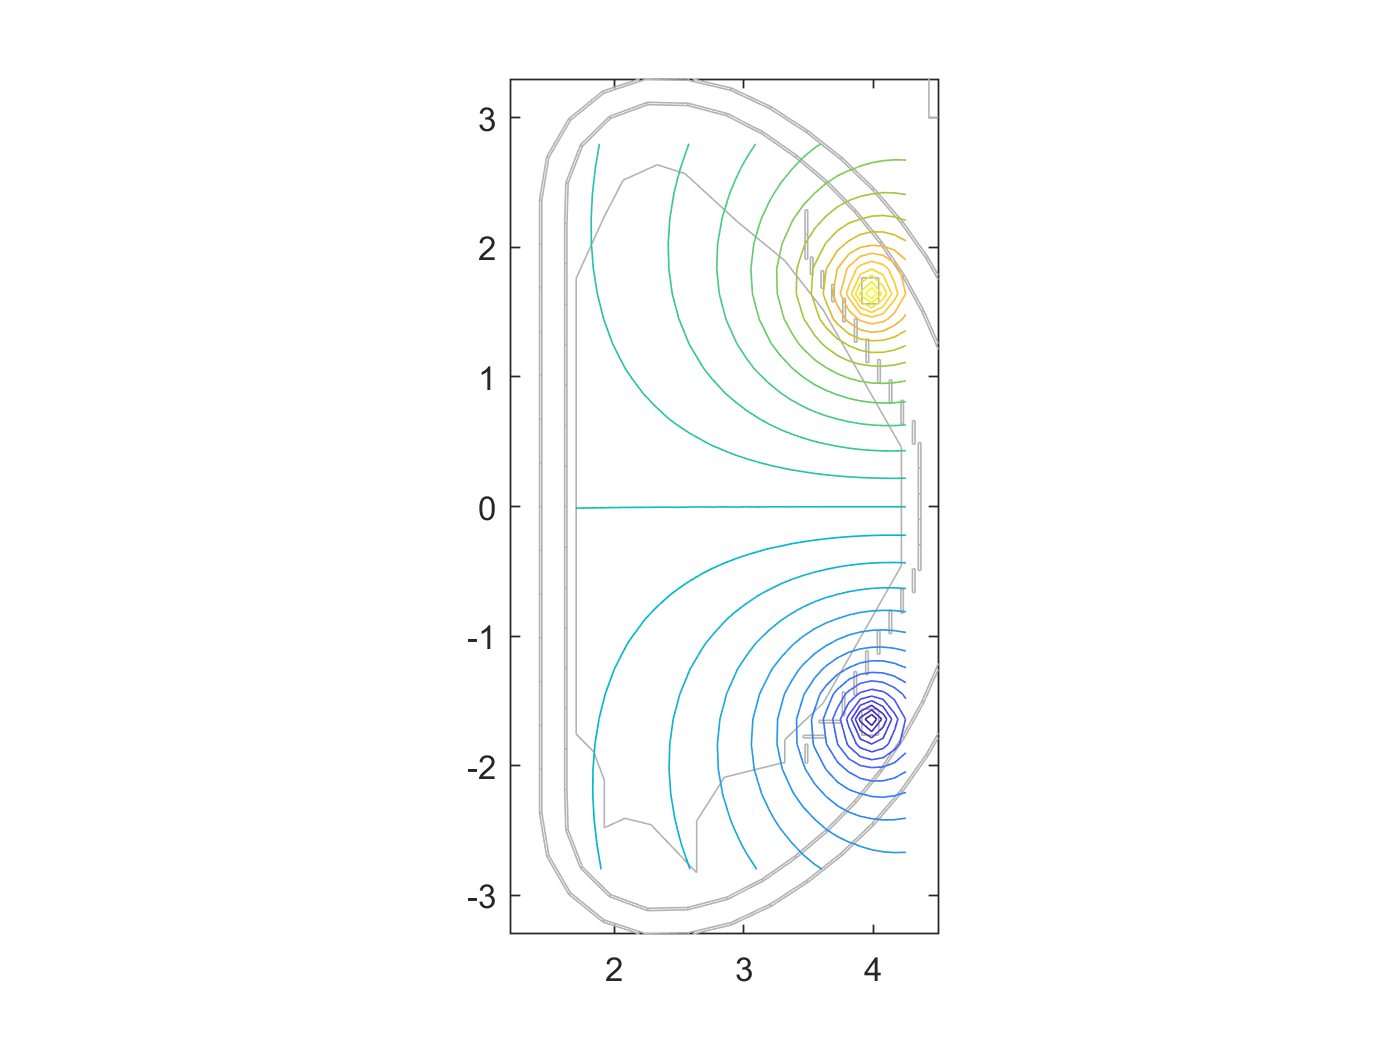

C_fg = pm.C(i_fg,:);
dy   = C_fg*dI;

R_fg = reshape(r_fg,30,30);
Z_fg = reshape(z_fg,30,30);
dY   = reshape(dy,30,30);

figure
plot_mesh(plasmaless.Input_struct);
hold on
contour(R_fg,Z_fg,dY,31)
xlim([ 1.2 4.5])
ylim([-3.3 3.3])

As you can see from the picture, the field is approximately radial (and exactly radial at the midplane of the vacuum chamber), so it is capable of providing a net vertical force on the plasma ring - exactly what we need.

## VS model

To design our VS system, we need a model to work on. Instead of using the simple filamentary model seen before, we will use a plasma linearized model generated by using the CREATE-L code.

Let's load our linearized model (just for reference, this is a snapshot of JT-60SA Scenario #2 at the Start of Flat-top)

modelName = fullfile(pwd,'models','SOF@18d66s_FG.mat'); % specify model's path
model = load(modelName); % load model variables into a structure

and compute the linearized model matrices (we put them into a structure for ease of reference)

lm.A = -model.L\model.R;
lm.B =  model.L\eye(size(model.L));
lm.C =  model.C;
lm.D =  zeros(size(lm.C,1), size(lm.B,2)); % again, just a bunch of zeros
lm.E = -model.L\model.LE;
lm.F =  model.F;

Now, we need to define the inputs and outputs of our VS system. As we said, for the VS system on JT-60SA we want to use the *imbalance current *between the in-vessel circuits*.* We simply choose as our control input the voltage to these circuits (VSU-VSL) and connect them in anti-series.

% VSU-VSL are the 11th and 12th inputs
lm.B = lm.B(:,11)-lm.B(:,12);
lm.D = lm.D(:,11)-lm.D(:,12);

Then, we need to choose our outputs. The outputs for the VS system are usually the plasma centroid vertical velocity $\dot{z}_p(t)$ and the actuator current, in our case $(I_{VSU}-I_{VSL})/2$. We start by taking the vertical position and the imbalance current as follows

% Identify output positions
i_out = get_y_idx(model.y_type,{'VSU','VSL','Zpl'},1);

% Re-assign C ...
C_imbalance = (lm.C(i_out(1),:)-lm.C(i_out(2),:))/2;
C_zp        =  lm.C(i_out(3),:);
lm.C = [C_imbalance; C_zp];
% ... D
D_imbalance = (lm.D(i_out(1),:)-lm.D(i_out(2),:))/2;
D_zp        =  lm.D(i_out(3),:);
lm.D = [D_imbalance; D_zp];
% ... and F (just for consistency, we'll not use it!)
F_imbalance = (lm.F(i_out(1),:)-lm.F(i_out(2),:))/2;
F_zp        =  lm.F(i_out(3),:);
lm.F = [F_imbalance; F_zp];

We can define a plasma state-space object as

VS_sys = ss(lm.A,lm.B,lm.C,lm.D,...
            'inputname',{'VSU-VSL'},'outputname',{'(IVSU-IVSL)/2','Zp'});

and verify that our model has an unstable eigenvalue (aka a pole in the right half of the complex plane)

max(real(eig(VS_sys)))

ans = 3.3905

corresponding to a time constant of

1/max(real(eig(VS_sys)))

ans = 0.2949

Incidentally, the next few eigenvalues have 0 real part, and are due to the superconducting coils (which theoretically behave as integrators)

esort(real(eig(VS_sys)))

ans = 	1.0e+03 *

    0.0034
         0
         0
         0
         0
         0
         0
         0
         0
         0


We'll carry out the design of the controller on a simple case, where we consider an ideal derivative of the vertical plasma position. Since, in our model, we have


$$\dot{x}(t)=Ax(t)+Bu(t) \\
y(t) = Cx(t)+Du(t)$$


we can compute the derivative of y as


$$\dot{y}(t) = CAx(t)+CBu(t) + D\dot{u}(t)$$


In our case, D is just a bunch of zeros, so we can neglect the last term. Applying this procedure to the second output of our model, we have

VS_olsys = ss(VS_sys.a, ...
            VS_sys.b, ...
            [VS_sys.c; VS_sys.c(2,:)*VS_sys.a], ...
            [VS_sys.d; VS_sys.c(2,:)*VS_sys.b]);

Again, assign I/O names (this extra step will turn out to be quite handy in a moment)

VS_olsys.outputname = {'(IVSU-IVSL)/2','Zp','Zdot'};
VS_olsys.inputname  = {'VSU-VSL'};

## VS design

Next step is to define a test case for our control system. A worst-case scenario often use to validate a VS design is to consider a so-called VDE (Vertical Displacement Event), i.e. a displacement along the unstable current pattern which results into a given $\delta z_p$. 

First we need to get our unstable direction, which is the eigenvector of the A matrix associated to the unstable eigenvalue

[V,D] = eig(lm.A);
[gamma,i_gamma] = max(real(diag(D))); % gamma is the growth-rate of our unstable mode
x_vde = V(:,i_gamma); % normalized to |x| = 1A

The (very small) plasma vertical displacement associated to this unstable pattern is

z0 = lm.C(2,:)*x_vde

z0 = -1.1260e-06

so, if we ask (for instance) a 2cm vde

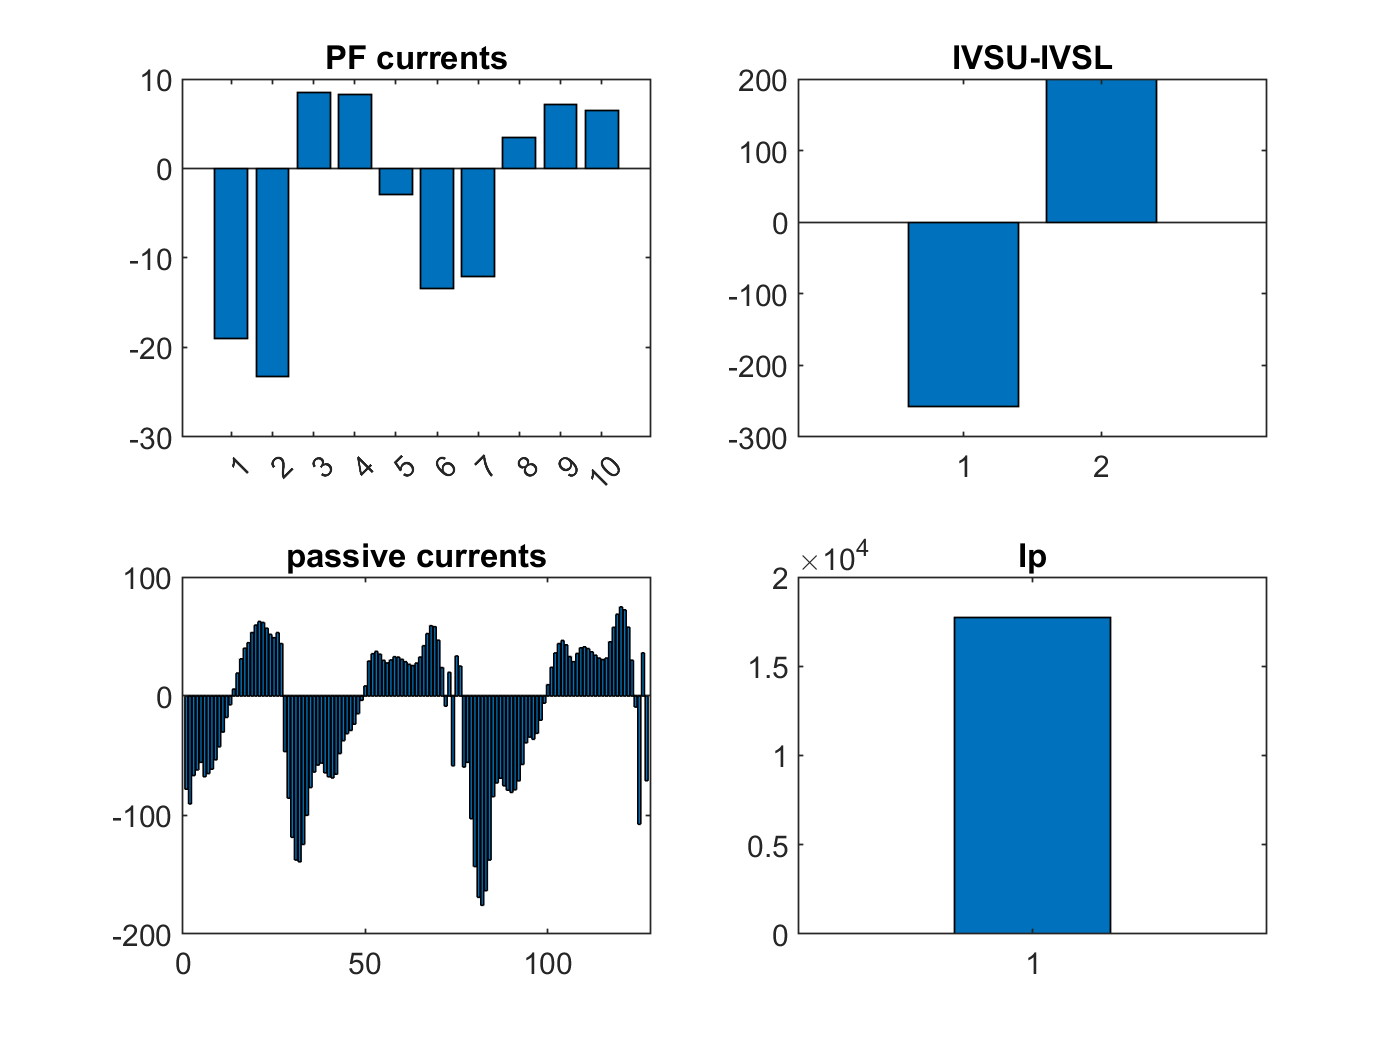

x0 = x_vde*2e-2/z0;
figure
subplot(221)
bar(x0(1:10))
title('PF currents')
subplot(222)
bar(x0(11:12))
title('IVSU-IVSL')
subplot(223)
bar(x0(13:end-1))
title('passive currents')
subplot(224)
bar(x0(end))
title('Ip')

There are different ways to design a VS system. Let's go for a very simple one. First, of all, we fix the structure of our controller as


$$u = K_1 I_{VS} + K_2 \dot{z}_p(t)$$


(notice that in general the velocity gain is scaled by the scenario plasma current, $K_2 = \bar{K}_2 I_{p0}$).

For this first exercise, we will use the optimization tools provided by matlab. The objective function is defined in the file VS_objf.m, and is just a weighted sum of the squares of the imbalance current and the plasma vertical velocity samples obtained from a 0.5s simulation. We look for its minimum

Ts    = 1e-3; % sampling time for the control system
Tspan = (0:Ts:0.5)';

% Just some options for the solver
options = optimset('MaxIter',1000,'MaxFunEvals',1500,'Display','Iter');

% Solve the optimization problem
[K_opt,J_opt] = fmincon(@(k)VS_objf(k,VS_olsys,x0,Tspan),[-0.03 800],[],[],[],[],[],[],@(k)VS_nlcon(k,VS_olsys),options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.097972e+07    0.000e+00    1.315e+08
Objective function returned NaN; trying a new point...
    1      11    8.900048e+06    0.000e+00    2.451e+07    5.025e-01
Objective function returned NaN; trying a new point...
    2      15    8.890284e+06    0.000e+00    2.438e+07    7.071e-01
    3      18    7.793652e+06    0.000e+00    1.095e+07    1.055e+02
    4      21    7.419541e+06    0.000e+00    6.270e+06    6.472e+01
    5      24    7.184043e+06    0.000e+00    2.514e+06    7.794e+01
    6      27    7.114772e+06    0.000e+00    5.807e+05    5.796e+01
    7      30    7.100124e+06    0.000e+00    3.158e+05    3.781e+01
    8      33    7.096243e+06    0.000e+00    6.431e+05    2.268e+01
    9      36    7.090517e+06    0.000e+00    9.446e+05    3.753e+01
   10      39    7.077066e+06    0.000e+00    1.282e+06    9.072e+01
   11 

Finally, we define our controller as a (static) ss object. Notice that we can use the I/O names to automatically make the connections between the blocks!

VS_contr = ss(K_opt,'inputname',{'(IVSU-IVSL)/2','Zdot'},'outputname',{'VSU-VSL'});

## Test

### Test #1

Now it's time to test our controller. Define the closed-loop system by connecting the controller to the open-loop model of our plant

VS_clsys = feedback(VS_olsys,VS_contr,'name'); % the 'names' option indicates that the connections are made automatically based on the I/O tags

Then simulate and plot some figures

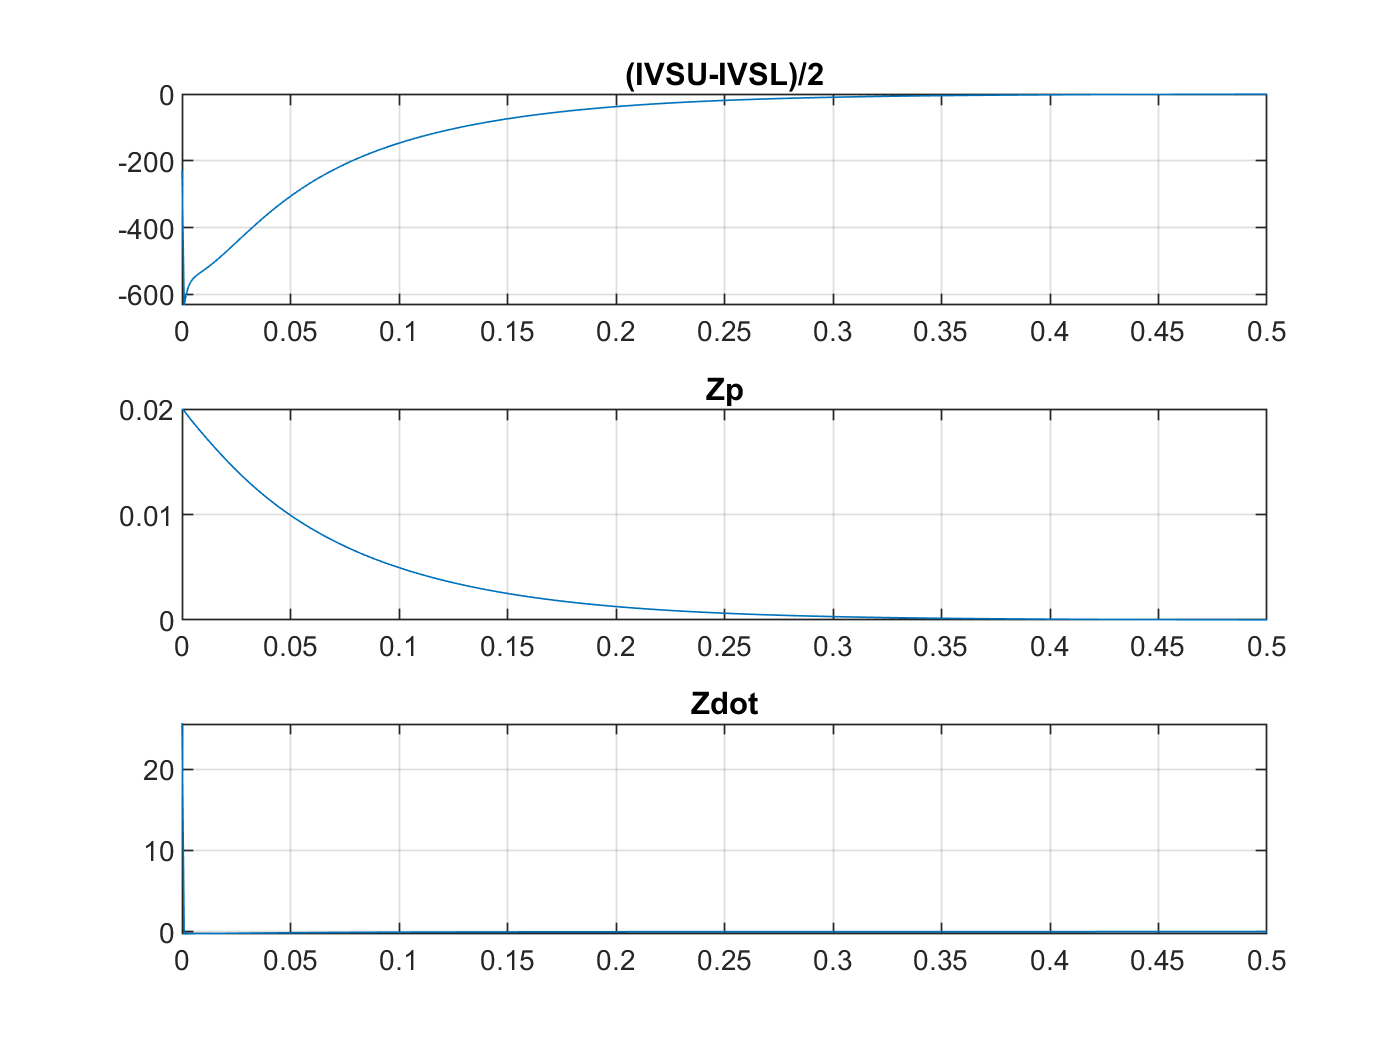

[y,t] = lsim(VS_clsys,Tspan*0,Tspan,x0,'zoh');

figure
subplot(311)
plot(t,y(:,1))
title(VS_olsys.outputname{1})
grid on
subplot(312)
plot(t,y(:,2))
title(VS_olsys.outputname{2})
grid on
subplot(313)
plot(t,y(:,3))
title(VS_olsys.outputname{3})
grid on

Good: the velocity is brought to 0 very rapidly, which is what we wanted. Perhaps even a bit *too *rapidly - we'll discuss this in a moment.

### Test #2 (a cautionary tale)

In general, not only we need a *fast *controller, but also a *robust *one. Control theory provides different ways to check the robustness properties of our closed-loop system, as we want to make sure that our controller works even when disturbances/uncertainties come at play. In this case, we can take a look at the Nyquist plot of our solution

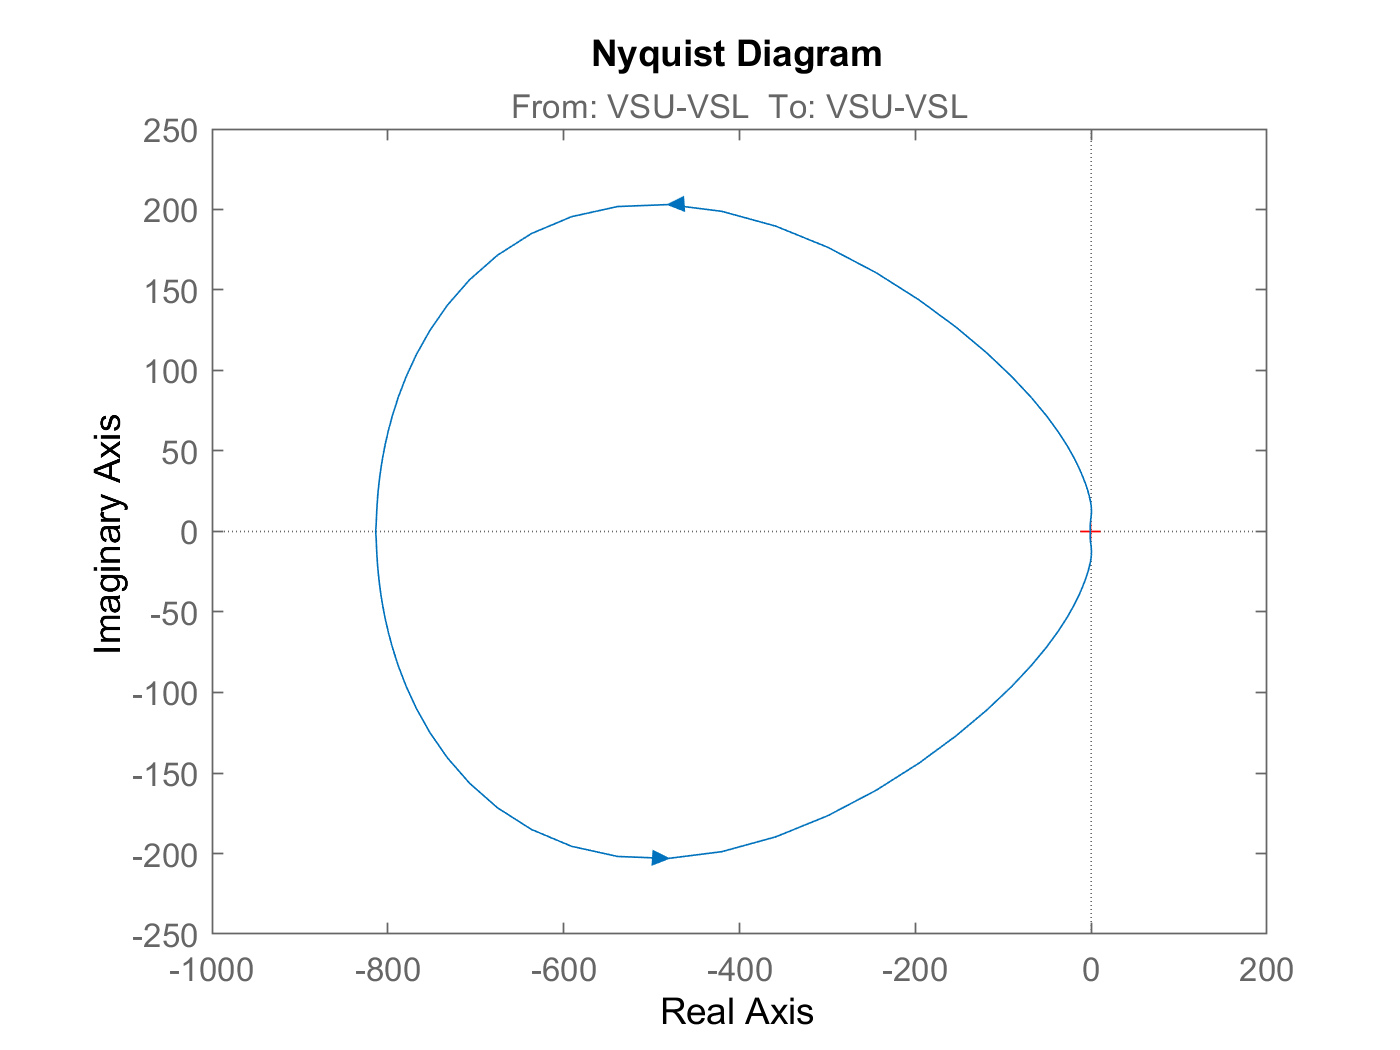

figure
nyquist(VS_contr*VS_olsys([1 3],:))

Ugly! Let's take a closer look

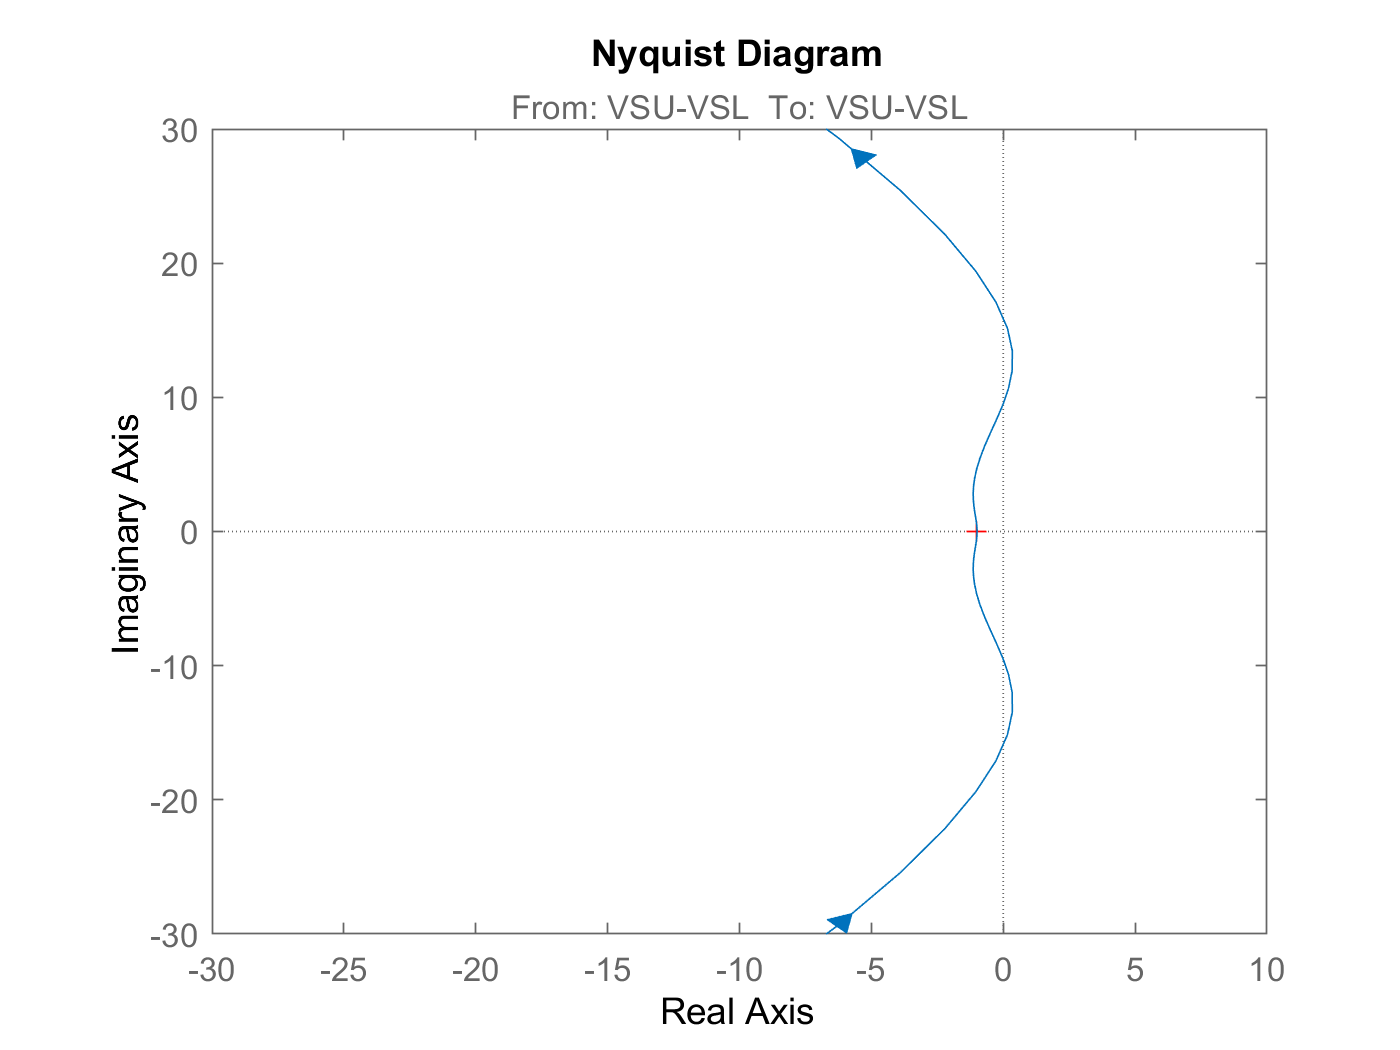

figure
h=nyquistplot(VS_contr*VS_olsys([1 3],:));
opt = getoptions(h);
opt.XLim = {[-30, 10]};
opt.YLim = {[-30, 30]};
setoptions(h,opt);

We are *extremely *close to instability! 

In general, the VS system is a quite fast/delicate controller, for which the power-supplies could have a significant impact. For this reason, it's a good idea to take into account the power supplies of our in-vessel coils explicitly. The model we'll consider for JT-60SA's power supplies is the following (1st order dynamics + pure delay)

PS_sys = tf(1,[3e-3,1]);    % 1st order dynamics
PS_sys.inputDelay = 1.5e-3; % pure delay
PS_sys.inputname  = {'VSU-VSL'};
PS_sys.outputname = {'VSU-VSL'}; % just use the same name

Moreover, usually the derivative of the vertical position of the plasma is obtained numerically by means of a High-Pass Filter (HPF)

HPF = tf([1,0], [1e-3,1])

HPF =
 
       s
  -----------
  0.001 s + 1
 
Continuous-time transfer function.



We can verify that this is indeed a derivative filter, at least for (relatively) low frequency signals. Consider the following example

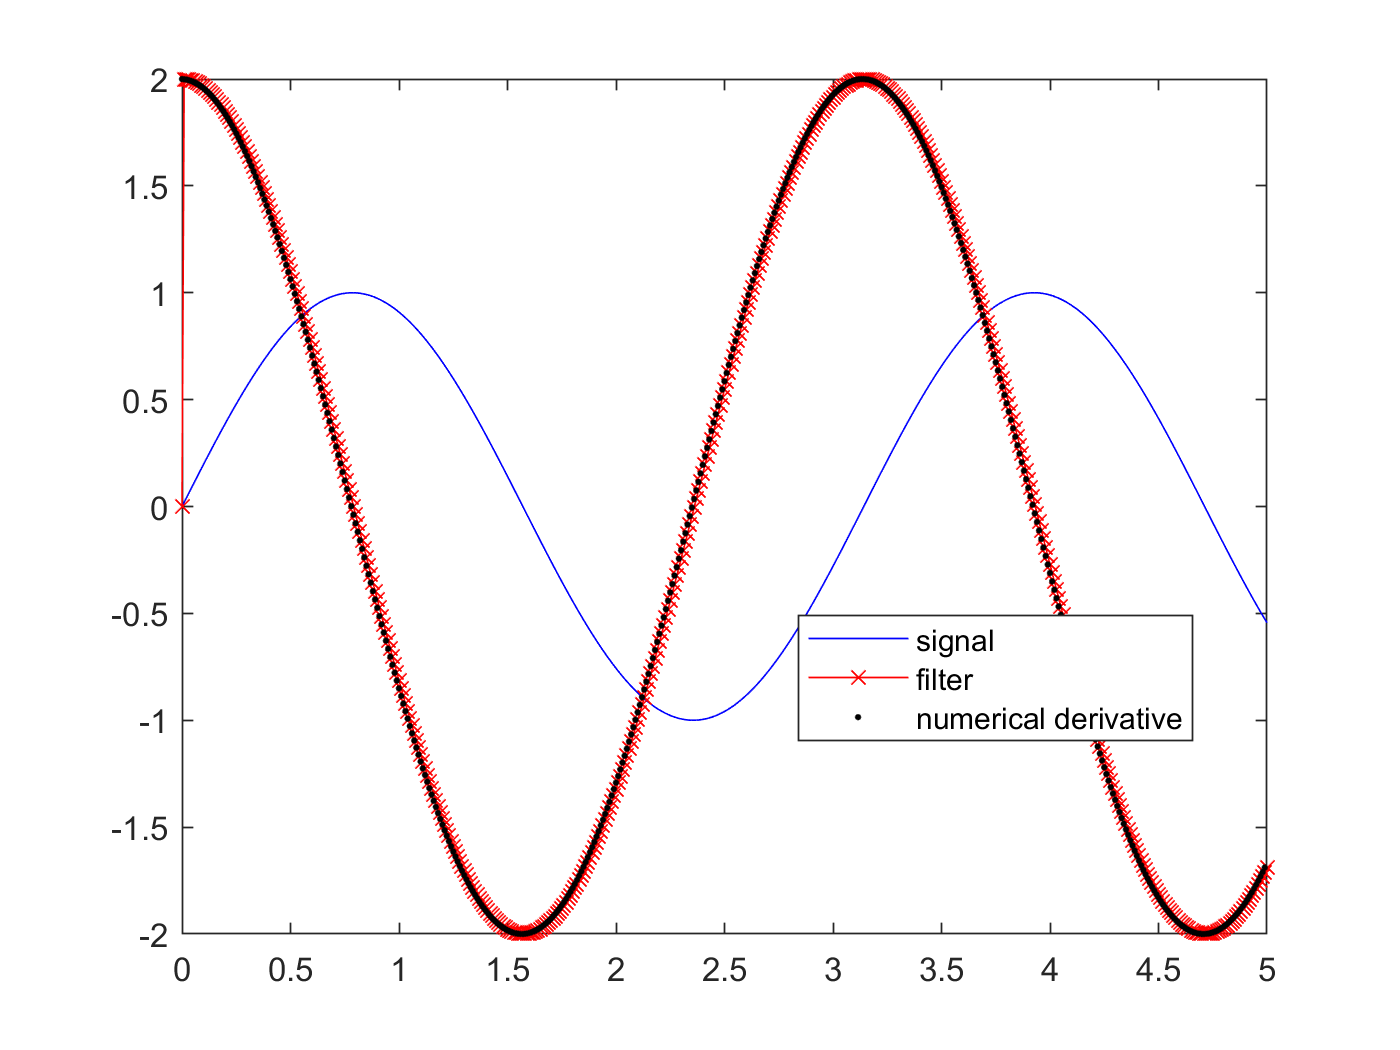

x = 0:1e-2:5;
y = sin(2*x);
% y = sin(1000*x); % This case will NOT work (the sinusoid's frequency is too high!)

dy = lsim(HPF,y,x);
figure
plot(x,y,'b',x,dy,'x-r',x(1:end-1), diff(y)./diff(x), '.k')
legend({'signal','filter','numerical derivative'},'location','best')

Moreover, for the simulation we'll need to feed-through the IV current, so let's turn our HPF into a matrix

HPF = [1 0; ...
       0 1; ...
       0 HPF]; 
HPF.inputname  = {'(IVSU-IVSL)/2','Zp'};
HPF.outputname = {'(IVSU-IVSL)/2','Zp','Zdot'};

We can now connect our systems (OL just stands for 'open-loop' here)

VS_olsys2 = series(PS_sys, VS_sys,'name');
VS_olsys2 = series(VS_olsys2,HPF, 'name'); 

And see what happens now with the controller we had found before

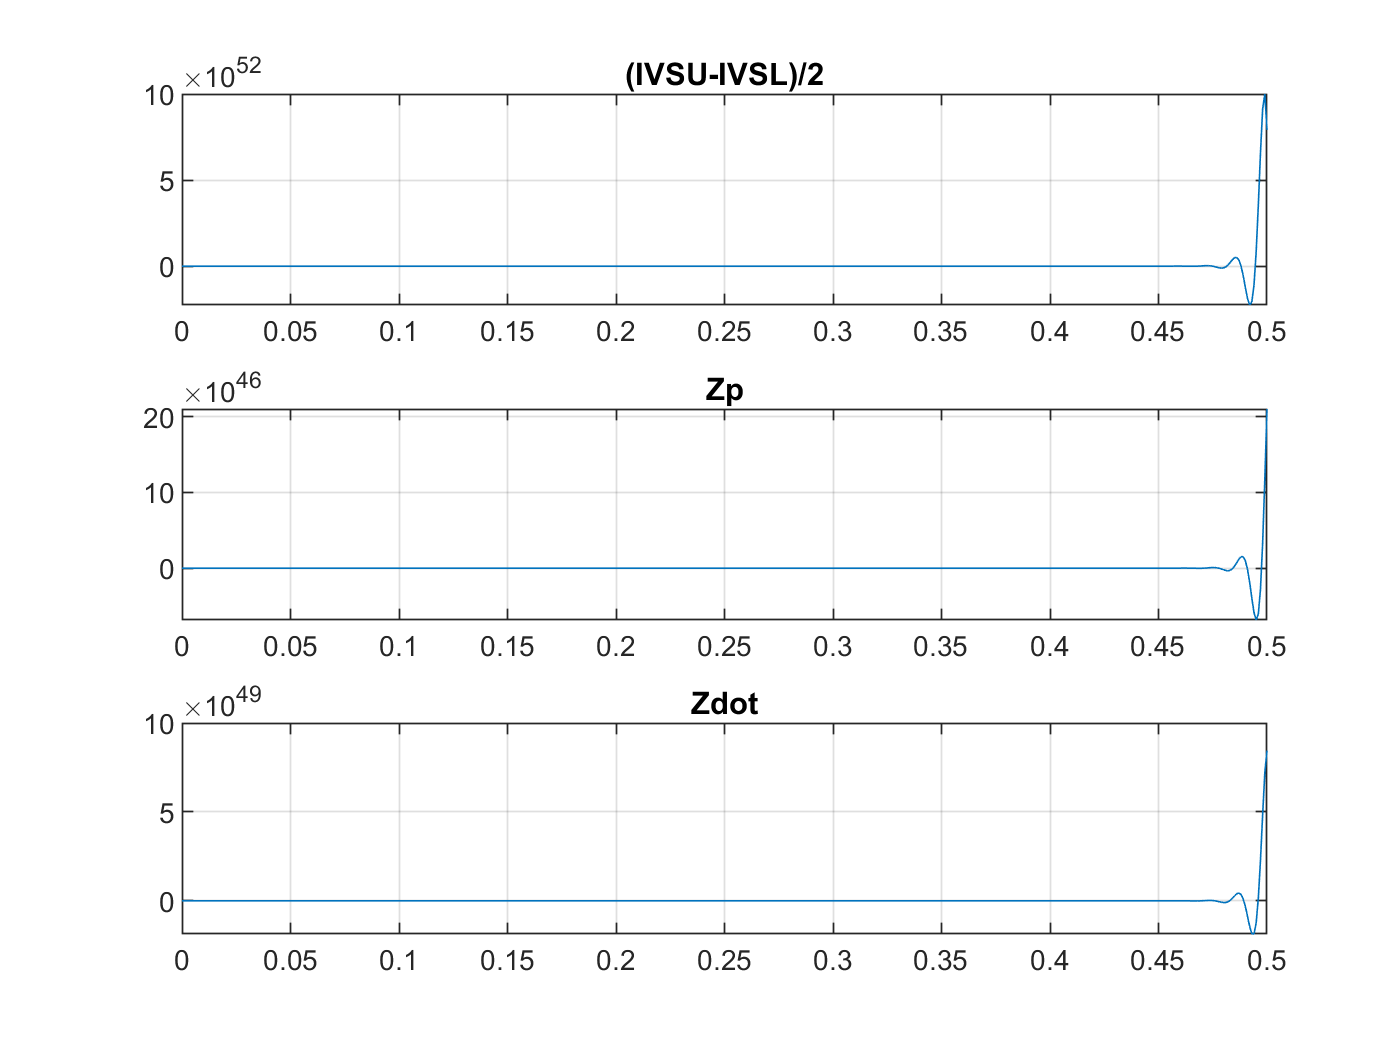

VS_clsys2 = feedback(VS_olsys2,VS_contr,'name');

VS_clsys2.InputDelay = VS_clsys2.InternalDelay;
VS_clsys2.InternalDelay = 0;
[y,t] = lsim(VS_clsys2,Tspan*0,Tspan,[0;x0;0],'zoh');

figure
subplot(311)
plot(t,y(:,1))
title(VS_olsys.outputname{1})
grid on
subplot(312)
plot(t,y(:,2))
title(VS_olsys.outputname{2})
grid on
subplot(313)
plot(t,y(:,3))
title(VS_olsys.outputname{3}) 
grid on

boom! It broke...

Sometimes, very good performance means very poor robustness :(

Let's look again at our Nyquist plot

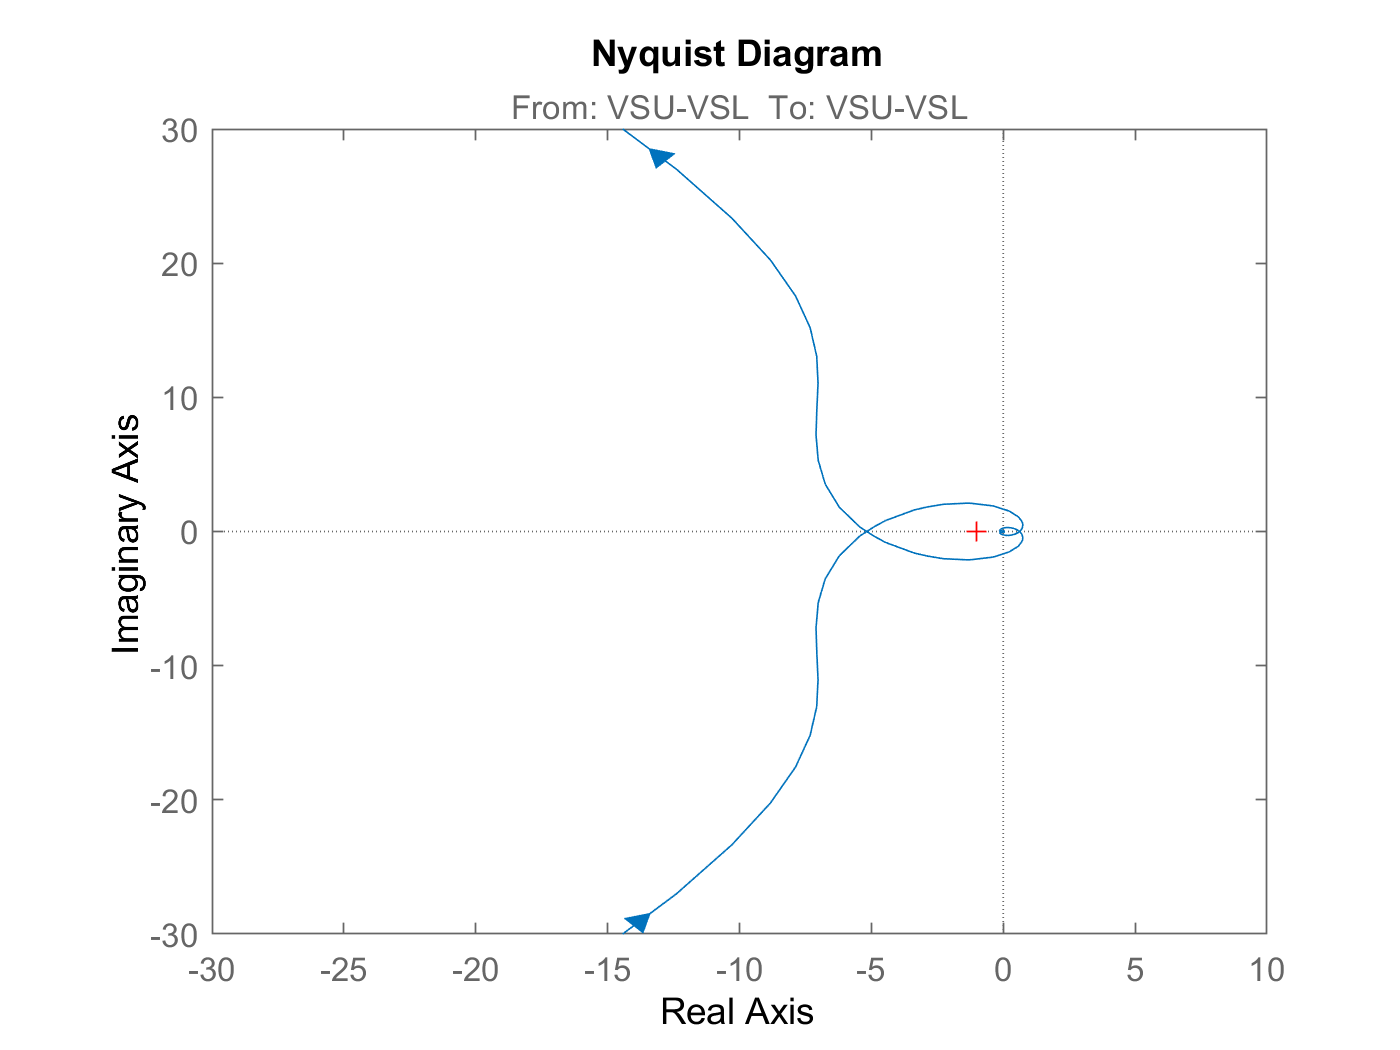

figure
h=nyquistplot(VS_contr*VS_olsys2([1 3],:));
opt = getoptions(h);
opt.XLim = {[-30, 10]};
opt.YLim = {[-30, 30]};
setoptions(h,opt);

As you can see, now we have one encirclement in the cw direction. The "spirals" close to the origin are due to the delay introduced by the power supplies. 

We can escape this circle by reducing the controller gain. Let's try a "quieter" controller

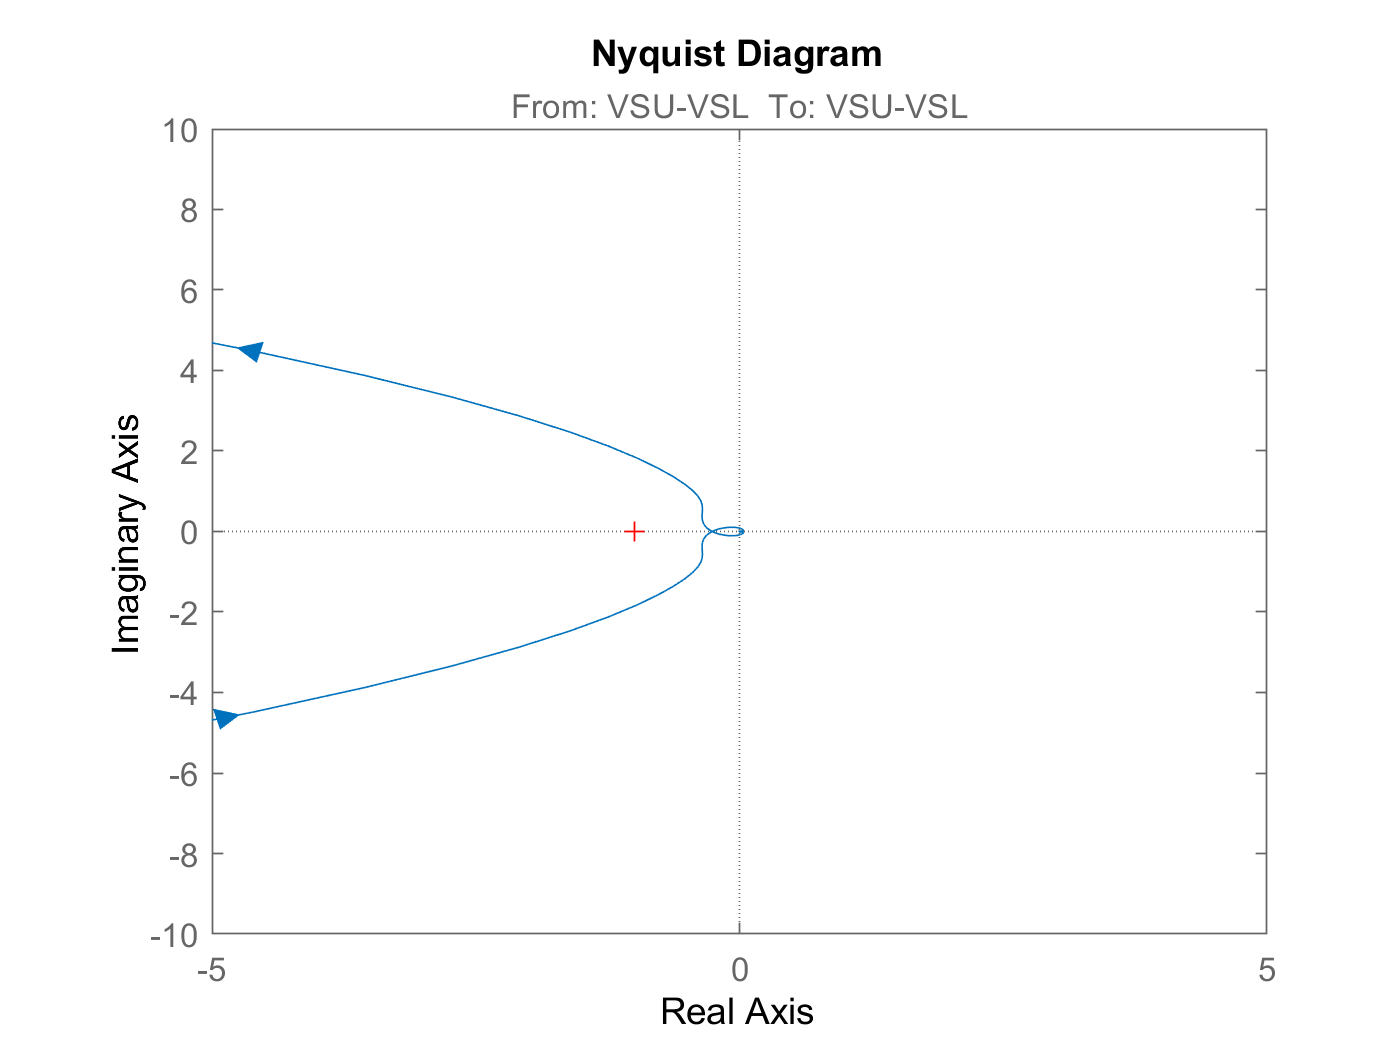

VS_contr2 = VS_contr*0.05; % lower the gain of a factor 1/20: this is a much slower controller!
VS_clsys2 = feedback(VS_olsys2,VS_contr2,'name');

figure
h = nyquistplot(VS_contr2*VS_olsys2([1 3],:));
opt = getoptions(h);
opt.XLim = {[-5, 5]};
opt.YLim = {[-10, 10]};
setoptions(h,opt);

We escaped the smaller loop and now the controller should work. Let's try it in simulation

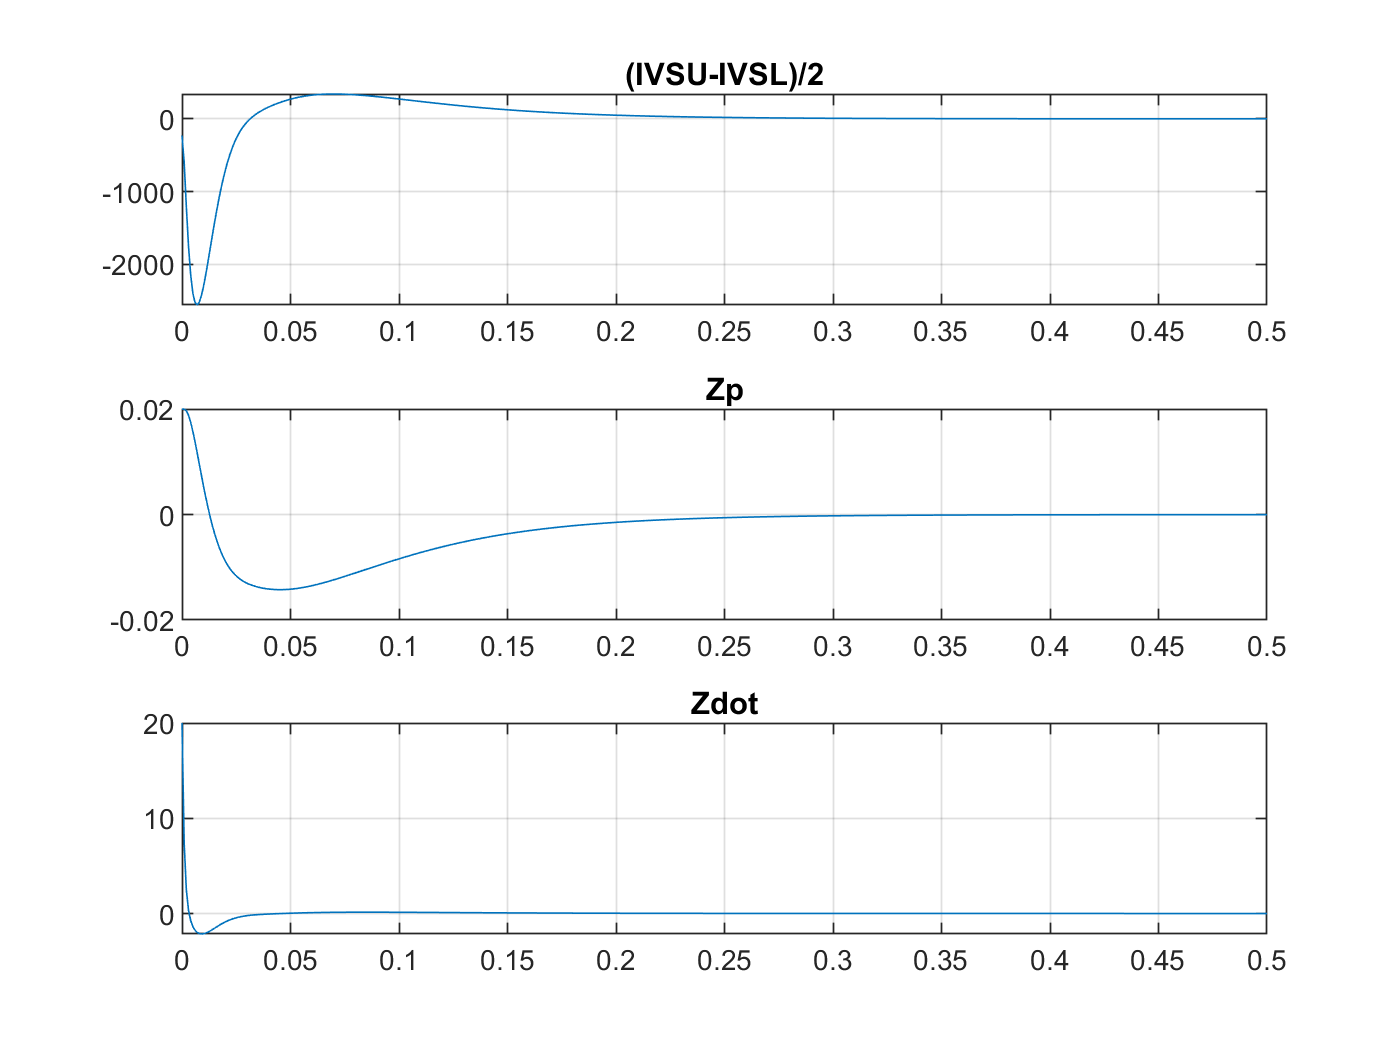

VS_clsys2.InputDelay = VS_clsys2.InternalDelay;
VS_clsys2.InternalDelay = 0; % this is just a quick'n'dirty trick to make lsim work
[y,t] = lsim(VS_clsys2,Tspan*0,Tspan,[0;x0;0],'zoh');

figure
subplot(311)
plot(t,y(:,1))
grid on
title(VS_olsys.outputname{1})

subplot(312)
plot(t,y(:,2))
grid on
title(VS_olsys.outputname{2}) 

subplot(313)
plot(t,y(:,3))
grid on 
title(VS_olsys.outputname{3}) % ...but safer :)

Not bad! Finally, we save the controller for later use

VS_contr = VS_contr2;
save ./data/VS_contr VS_contr

## Bonus: experiments

We tested a similar VS system on the EAST tokamak a few years ago. During one experiment (EAST pulse #77472), the rest of the controllers were (accidentally) switched off. Anyway, the VS was able to provide a nice and stable plasma for more than 7 seconds, as you can see in the figure below.